`Copyright 2026 UIUC Yingjie Zhang Group`

`   Licensed under the Apache License, Version 2.0 (the "License");`

`   you may not use this file except in compliance with the License.`

`   You may obtain a copy of the License at`

`     http://www.apache.org/licenses/LICENSE-2.0`

`   Unless required by applicable law or agreed to in writing, software`

`   distributed under the License is distributed on an "AS IS" BASIS,`

`   WITHOUT WARRANTIES OR CONDITIONS OF ANY KIND, either express or implied.`

`   See the License for the specific language governing permissions and`

`   limitations under the License.`

## Construct the substrate coordinates

% construct the graphite substrate atomic coordinates

% construct the repeating unit. Unit: nm
bondlength = 0.142; % carbon-carbon bond length in graphite
ringwidth = round(sqrt(3)*bondlength,4); % the width of a hexagonal carbon ring

CarbonX1 = [0, -ringwidth/2, -ringwidth/2, 0, 0, -ringwidth/2, -ringwidth/2, 0,...
    0, -ringwidth/2, -ringwidth/2, 0, 0, -ringwidth/2, -ringwidth/2, 0, 0, ...
    -ringwidth/2, -ringwidth/2, 0, 0, -ringwidth/2, -ringwidth/2, 0, 0, ...
    -ringwidth/2, -ringwidth/2, 0, 0, -ringwidth/2, -ringwidth/2, 0, 0, ...
    -ringwidth/2, -ringwidth/2, 0];
CarbonY11 = [2*bondlength, 1.5*bondlength, 0.5*bondlength, 0];
CarbonY1 = [];
% repeat the unit in y direction
for i=9:-1:1
    CarbonY1 = [CarbonY1, 3*bondlength*(i-5).*[1,1,1,1]+CarbonY11];
end
%
coor=[];

% construct a large plane of atom for later use
for i=1:50
    X1 = CarbonX1+(i-1)*ringwidth;
    newcoor = [X1', CarbonY1'];
    coor = [coor; newcoor];
end


%flat area coordinate. Four layers are included in the calculation, each layer 
% containing 1080 atoms. Layers have a ABAB stacking. Interlayer spacing is 0.34 nm.
% x coordinates of substrate atoms are [-0.861, 6.396]nm but the calculated density 
% map contains only area of 0-5 nm in x.

spacing = 0.34; % interlayer spacing of graphene layers in graphite

coor1 = [coor(1:30*36,1)-3*ringwidth,coor(1:30*36,2),zeros([30*36,1])];

% first layer under z=0
coor1u = [coor(1:30*36,1)-3*ringwidth,coor(1:30*36,2)+bondlength,ones([30*36,1])*-spacing];
% second layer under z=0
coor2u = [coor(1:30*36,1)-3*ringwidth,coor(1:30*36,2),ones([30*36,1])*-spacing*2]; 
% third layer under z=0
coor3u = [coor(1:30*36,1)-3*ringwidth,coor(1:30*36,2)+bondlength,ones([30*36,1])*-spacing*3]; 

% all atom coordinates. A total of 4320 atoms are used.
atomcoor = [coor1;coor1u; coor2u; coor3u]; 
% for your system: replace atomcoor with your substrate atomic positions

% substrate coordinates for a mono-step area

coor1 = [coor(1:30*36,1)-3*ringwidth,coor(1:30*36,2),zeros([30*36,1])];
coor2 = [coor(1:30*36,1)-3*ringwidth,coor(1:30*36,2),zeros([30*36,1])];

% first layer under z=0
coor1u = [coor(1:30*36,1)-3*ringwidth,coor(1:30*36,2)+bondlength,ones([30*36,1])*-spacing];
% second layer under z=0
coor2u = [coor(1:30*36,1)-3*ringwidth,coor(1:30*36,2),ones([30*36,1])*-spacing*2]; 
% third layer under z=0
coor3u = [coor(1:30*36,1)-3*ringwidth,coor(1:30*36,2)+bondlength,ones([30*36,1])*-spacing*3]; 

% all atom coordinates. A total of 4320 atoms are used.
atomcoor = [coor1; coor2; coor1u; coor2u; coor3u]; 

## Plot substrate atoms in x-y plane to check

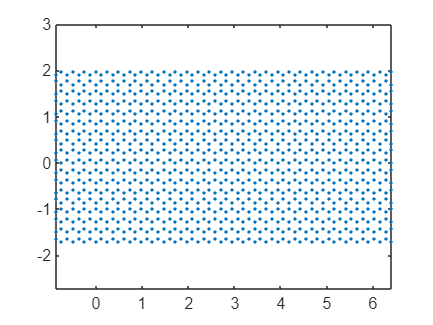

% plot the top layer
plot(coor1(:,1),coor1(:,2),'.')
axis equal

## **Create a 500 * 500 resolution density map **

% create the 500 * 500 mesh for 5 nm (x) * 2 nm (z) map
x = linspace(0,5,500); % unit: nm; pixel number: 500
z = linspace(0,2,500); % unit: nm; pixel number: 500
[X, Z] = meshgrid(x,z);
mapcoor = zeros([250000,3]);

% xyz coordinate of each mesh point of the 500*500 mesh
for i=1:250000
    mapcoor(i,1)=X(i);
    mapcoor(i,2)=0; % we calculate the x-z cross at y=0
    mapcoor(i,3)=Z(i);
end

## Calculate the SLS summation using matrix calculation

Due to the linear additivity of the SLS model, we divide the atoms into batches of 120 and employ matrix operations to accelerate the computation. We first calculate the contribution from the initial batch of 120 substrate atoms and add it to the final density map, then proceed sequentially to the subsequent batches. 

% initiate the density map
dens_map = zeros([500,500]);

% this is how many batches we need to do the calculation
bat_num = floor(length(atomcoor)/120); 
for i=1:bat_num
    calcoor = atomcoor(120*(i-1)+1:120*i,:); % coordinates of the substrate atoms

    % calculate the Euclidean distance of each mesh pixel-solid atom pair
    result = sum(calcoor.^2, 2) - 2 * calcoor * mapcoor.' + sum(mapcoor.^2, 2).';
    result = sqrt(result); % this is a 120*250000 array, it has 120 1*250000 
    % vectors storing the distance between each solid atom and every one of 
    % the 500*500 mesh points in the map
    
    % plug each distance into ETCF function to get the density 
    % contribution of each solid atom
    result2 = h(result);
    result = 0; % clear up memory
    
    % add up individual contribution from each atom and reshape it to 500*500
    hr1 = sum(result2,1);
    result2 = 0; % clear up memory
    % this is the density contribution from this batch of 120 atoms
    hr2 = reshape(hr1,[500,500]); 
    dens_map = dens_map + hr2; % add the density to the overall density map
end

## Plotting

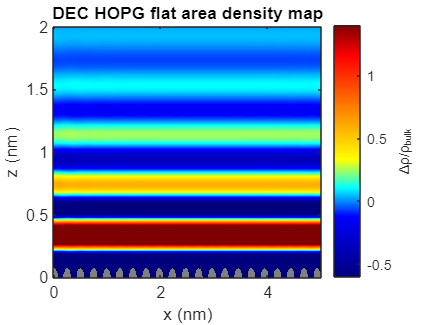

% plot the density map
imAlpha = ones(size(dens_map));
imAlpha(isnan(dens_map)) = 0;
imagesc([0 5], [0 2],dens_map, 'AlphaData',imAlpha)
ax = gca;    ax.YDir = 'normal';
% set NaN values to gray color, to mark the positions of substrate atoms
set(gca,'color',0.5*[1 1 1]); 

% we use a customized colormap to highlight different layers 
newjet512 = [0	0	0.5	;
0	0	0.504132231	;
0	0	0.508264463	;
0	0	0.512396694	;
0	0	0.516528926	;
0	0	0.520661157	;
0	0	0.524793388	;
0	0	0.52892562	;
0	0	0.533057851	;
0	0	0.537190083	;
0	0	0.541322314	;
0	0	0.545454545	;
0	0	0.549586777	;
0	0	0.553719008	;
0	0	0.55785124	;
0	0	0.561983471	;
0	0	0.566115702	;
0	0	0.570247934	;
0	0	0.574380165	;
0	0	0.578512397	;
0	0	0.582644628	;
0	0	0.58677686	;
0	0	0.590909091	;
0	0	0.595041322	;
0	0	0.599173554	;
0	0	0.603305785	;
0	0	0.607438017	;
0	0	0.611570248	;
0	0	0.615702479	;
0	0	0.619834711	;
0	0	0.623966942	;
0	0	0.628099174	;
0	0	0.632231405	;
0	0	0.636363636	;
0	0	0.640495868	;
0	0	0.644628099	;
0	0	0.648760331	;
0	0	0.652892562	;
0	0	0.657024793	;
0	0	0.661157025	;
0	0	0.665289256	;
0	0	0.669421488	;
0	0	0.673553719	;
0	0	0.67768595	;
0	0	0.681818182	;
0	0	0.685950413	;
0	0	0.690082645	;
0	0	0.694214876	;
0	0	0.698347107	;
0	0	0.702479339	;
0	0	0.70661157	;
0	0	0.710743802	;
0	0	0.714876033	;
0	0	0.719008264	;
0	0	0.723140496	;
0	0	0.727272727	;
0	0	0.731404959	;
0	0	0.73553719	;
0	0	0.739669421	;
0	0	0.743801653	;
0	0	0.747933884	;
0	0	0.752066116	;
0	0	0.756198347	;
0	0	0.760330579	;
0	0	0.76446281	;
0	0	0.768595041	;
0	0	0.772727273	;
0	0	0.776859504	;
0	0	0.780991736	;
0	0	0.785123967	;
0	0	0.789256198	;
0	0	0.79338843	;
0	0	0.797520661	;
0	0	0.801652893	;
0	0	0.805785124	;
0	0	0.809917355	;
0	0	0.814049587	;
0	0	0.818181818	;
0	0	0.82231405	;
0	0	0.826446281	;
0	0	0.830578512	;
0	0	0.834710744	;
0	0	0.838842975	;
0	0	0.842975207	;
0	0	0.847107438	;
0	0	0.851239669	;
0	0	0.855371901	;
0	0	0.859504132	;
0	0	0.863636364	;
0	0	0.867768595	;
0	0	0.871900826	;
0	0	0.876033058	;
0	0	0.880165289	;
0	0	0.884297521	;
0	0	0.888429752	;
0	0	0.892561983	;
0	0	0.896694215	;
0	0	0.900826446	;
0	0	0.904958678	;
0	0	0.909090909	;
0	0	0.91322314	;
0	0	0.917355372	;
0	0	0.921487603	;
0	0	0.925619835	;
0	0	0.929752066	;
0	0	0.933884298	;
0	0	0.938016529	;
0	0	0.94214876	;
0	0	0.946280992	;
0	0	0.950413223	;
0	0	0.954545455	;
0	0	0.958677686	;
0	0	0.962809917	;
0	0	0.966942149	;
0	0	0.97107438	;
0	0	0.975206612	;
0	0	0.979338843	;
0	0	0.983471074	;
0	0	0.987603306	;
0	0	0.991735537	;
0	0	0.995867769	;
0	0	1	;
0	0.017241379	1	;
0	0.034482759	1	;
0	0.051724138	1	;
0	0.068965517	1	;
0	0.086206897	1	;
0	0.103448276	1	;
0	0.120689655	1	;
0	0.137931034	1	;
0	0.155172414	1	;
0	0.172413793	1	;
0	0.189655172	1	;
0	0.206896552	1	;
0	0.224137931	1	;
0	0.24137931	1	;
0	0.25862069	1	;
0	0.275862069	1	;
0	0.293103448	1	;
0	0.310344828	1	;
0	0.327586207	1	;
0	0.344827586	1	;
0	0.362068966	1	;
0	0.379310345	1	;
0	0.396551724	1	;
0	0.413793103	1	;
0	0.431034483	1	;
0	0.448275862	1	;
0	0.465517241	1	;
0	0.482758621	1	;
0	0.5	1	;
0	0.517241379	1	;
0	0.534482759	1	;
0	0.551724138	1	;
0	0.568965517	1	;
0	0.586206897	1	;
0	0.603448276	1	;
0	0.620689655	1	;
0	0.637931034	1	;
0	0.655172414	1	;
0	0.672413793	1	;
0	0.689655172	1	;
0	0.706896552	1	;
0	0.724137931	1	;
0	0.74137931	1	;
0	0.75862069	1	;
0	0.775862069	1	;
0	0.793103448	1	;
0	0.810344828	1	;
0	0.827586207	1	;
0	0.844827586	1	;
0	0.862068966	1	;
0	0.879310345	1	;
0	0.896551724	1	;
0	0.913793103	1	;
0	0.931034483	1	;
0	0.948275862	1	;
0	0.965517241	1	;
0	0.982758621	1	;
0	1	1	;
0.017241379	1	0.982758621	;
0.034482759	1	0.965517241	;
0.051724138	1	0.948275862	;
0.068965517	1	0.931034483	;
0.086206897	1	0.913793103	;
0.103448276	1	0.896551724	;
0.120689655	1	0.879310345	;
0.137931034	1	0.862068966	;
0.155172414	1	0.844827586	;
0.172413793	1	0.827586207	;
0.189655172	1	0.810344828	;
0.206896552	1	0.793103448	;
0.224137931	1	0.775862069	;
0.24137931	1	0.75862069	;
0.25862069	1	0.74137931	;
0.275862069	1	0.724137931	;
0.293103448	1	0.706896552	;
0.310344828	1	0.689655172	;
0.327586207	1	0.672413793	;
0.344827586	1	0.655172414	;
0.362068966	1	0.637931034	;
0.379310345	1	0.620689655	;
0.396551724	1	0.603448276	;
0.413793103	1	0.586206897	;
0.431034483	1	0.568965517	;
0.448275862	1	0.551724138	;
0.465517241	1	0.534482759	;
0.482758621	1	0.517241379	;
0.5	1	0.5	;
0.517241379	1	0.482758621	;
0.534482759	1	0.465517241	;
0.551724138	1	0.448275862	;
0.568965517	1	0.431034483	;
0.586206897	1	0.413793103	;
0.603448276	1	0.396551724	;
0.620689655	1	0.379310345	;
0.637931034	1	0.362068966	;
0.655172414	1	0.344827586	;
0.672413793	1	0.327586207	;
0.689655172	1	0.310344828	;
0.706896552	1	0.293103448	;
0.724137931	1	0.275862069	;
0.74137931	1	0.25862069	;
0.75862069	1	0.24137931	;
0.775862069	1	0.224137931	;
0.793103448	1	0.206896552	;
0.810344828	1	0.189655172	;
0.827586207	1	0.172413793	;
0.844827586	1	0.155172414	;
0.862068966	1	0.137931034	;
0.879310345	1	0.120689655	;
0.896551724	1	0.103448276	;
0.913793103	1	0.086206897	;
0.931034483	1	0.068965517	;
0.948275862	1	0.051724138	;
0.965517241	1	0.034482759	;
0.982758621	1	0.017241379	;
1	1	0	;
1	0.995260664	0	;
1	0.990521327	0	;
1	0.985781991	0	;
1	0.981042654	0	;
1	0.976303318	0	;
1	0.971563981	0	;
1	0.966824645	0	;
1	0.962085308	0	;
1	0.957345972	0	;
1	0.952606635	0	;
1	0.947867299	0	;
1	0.943127962	0	;
1	0.938388626	0	;
1	0.933649289	0	;
1	0.928909953	0	;
1	0.924170616	0	;
1	0.91943128	0	;
1	0.914691943	0	;
1	0.909952607	0	;
1	0.90521327	0	;
1	0.900473934	0	;
1	0.895734597	0	;
1	0.890995261	0	;
1	0.886255924	0	;
1	0.881516588	0	;
1	0.876777251	0	;
1	0.872037915	0	;
1	0.867298578	0	;
1	0.862559242	0	;
1	0.857819905	0	;
1	0.853080569	0	;
1	0.848341232	0	;
1	0.843601896	0	;
1	0.838862559	0	;
1	0.834123223	0	;
1	0.829383886	0	;
1	0.82464455	0	;
1	0.819905213	0	;
1	0.815165877	0	;
1	0.81042654	0	;
1	0.805687204	0	;
1	0.800947867	0	;
1	0.796208531	0	;
1	0.791469194	0	;
1	0.786729858	0	;
1	0.781990521	0	;
1	0.777251185	0	;
1	0.772511848	0	;
1	0.767772512	0	;
1	0.763033175	0	;
1	0.758293839	0	;
1	0.753554502	0	;
1	0.748815166	0	;
1	0.744075829	0	;
1	0.739336493	0	;
1	0.734597156	0	;
1	0.72985782	0	;
1	0.725118483	0	;
1	0.720379147	0	;
1	0.71563981	0	;
1	0.710900474	0	;
1	0.706161137	0	;
1	0.701421801	0	;
1	0.696682464	0	;
1	0.691943128	0	;
1	0.687203791	0	;
1	0.682464455	0	;
1	0.677725118	0	;
1	0.672985782	0	;
1	0.668246445	0	;
1	0.663507109	0	;
1	0.658767773	0	;
1	0.654028436	0	;
1	0.6492891	0	;
1	0.644549763	0	;
1	0.639810427	0	;
1	0.63507109	0	;
1	0.630331754	0	;
1	0.625592417	0	;
1	0.620853081	0	;
1	0.616113744	0	;
1	0.611374408	0	;
1	0.606635071	0	;
1	0.601895735	0	;
1	0.597156398	0	;
1	0.592417062	0	;
1	0.587677725	0	;
1	0.582938389	0	;
1	0.578199052	0	;
1	0.573459716	0	;
1	0.568720379	0	;
1	0.563981043	0	;
1	0.559241706	0	;
1	0.55450237	0	;
1	0.549763033	0	;
1	0.545023697	0	;
1	0.54028436	0	;
1	0.535545024	0	;
1	0.530805687	0	;
1	0.526066351	0	;
1	0.521327014	0	;
1	0.516587678	0	;
1	0.511848341	0	;
1	0.507109005	0	;
1	0.502369668	0	;
1	0.497630332	0	;
1	0.492890995	0	;
1	0.488151659	0	;
1	0.483412322	0	;
1	0.478672986	0	;
1	0.473933649	0	;
1	0.469194313	0	;
1	0.464454976	0	;
1	0.45971564	0	;
1	0.454976303	0	;
1	0.450236967	0	;
1	0.44549763	0	;
1	0.440758294	0	;
1	0.436018957	0	;
1	0.431279621	0	;
1	0.426540284	0	;
1	0.421800948	0	;
1	0.417061611	0	;
1	0.412322275	0	;
1	0.407582938	0	;
1	0.402843602	0	;
1	0.398104265	0	;
1	0.393364929	0	;
1	0.388625592	0	;
1	0.383886256	0	;
1	0.379146919	0	;
1	0.374407583	0	;
1	0.369668246	0	;
1	0.36492891	0	;
1	0.360189573	0	;
1	0.355450237	0	;
1	0.3507109	0	;
1	0.345971564	0	;
1	0.341232227	0	;
1	0.336492891	0	;
1	0.331753555	0	;
1	0.327014218	0	;
1	0.322274882	0	;
1	0.317535545	0	;
1	0.312796209	0	;
1	0.308056872	0	;
1	0.303317536	0	;
1	0.298578199	0	;
1	0.293838863	0	;
1	0.289099526	0	;
1	0.28436019	0	;
1	0.279620853	0	;
1	0.274881517	0	;
1	0.27014218	0	;
1	0.265402844	0	;
1	0.260663507	0	;
1	0.255924171	0	;
1	0.251184834	0	;
1	0.246445498	0	;
1	0.241706161	0	;
1	0.236966825	0	;
1	0.232227488	0	;
1	0.227488152	0	;
1	0.222748815	0	;
1	0.218009479	0	;
1	0.213270142	0	;
1	0.208530806	0	;
1	0.203791469	0	;
1	0.199052133	0	;
1	0.194312796	0	;
1	0.18957346	0	;
1	0.184834123	0	;
1	0.180094787	0	;
1	0.17535545	0	;
1	0.170616114	0	;
1	0.165876777	0	;
1	0.161137441	0	;
1	0.156398104	0	;
1	0.151658768	0	;
1	0.146919431	0	;
1	0.142180095	0	;
1	0.137440758	0	;
1	0.132701422	0	;
1	0.127962085	0	;
1	0.123222749	0	;
1	0.118483412	0	;
1	0.113744076	0	;
1	0.109004739	0	;
1	0.104265403	0	;
1	0.099526066	0	;
1	0.09478673	0	;
1	0.090047393	0	;
1	0.085308057	0	;
1	0.08056872	0	;
1	0.075829384	0	;
1	0.071090047	0	;
1	0.066350711	0	;
1	0.061611374	0	;
1	0.056872038	0	;
1	0.052132701	0	;
1	0.047393365	0	;
1	0.042654028	0	;
1	0.037914692	0	;
1	0.033175355	0	;
1	0.028436019	0	;
1	0.023696682	0	;
1	0.018957346	0	;
1	0.014218009	0	;
1	0.009478673	0	;
1	0.004739336	0	;
1	0	0	;
0.992063492	0	0	;
0.984126984	0	0	;
0.976190476	0	0	;
0.968253968	0	0	;
0.96031746	0	0	;
0.952380952	0	0	;
0.944444444	0	0	;
0.936507937	0	0	;
0.928571429	0	0	;
0.920634921	0	0	;
0.912698413	0	0	;
0.904761905	0	0	;
0.896825397	0	0	;
0.888888889	0	0	;
0.880952381	0	0	;
0.873015873	0	0	;
0.865079365	0	0	;
0.857142857	0	0	;
0.849206349	0	0	;
0.841269841	0	0	;
0.833333333	0	0	;
0.825396825	0	0	;
0.817460317	0	0	;
0.80952381	0	0	;
0.801587302	0	0	;
0.793650794	0	0	;
0.785714286	0	0	;
0.777777778	0	0	;
0.76984127	0	0	;
0.761904762	0	0	;
0.753968254	0	0	;
0.746031746	0	0	;
0.738095238	0	0	;
0.73015873	0	0	;
0.722222222	0	0	;
0.714285714	0	0	;
0.706349206	0	0	;
0.698412698	0	0	;
0.69047619	0	0	;
0.682539683	0	0	;
0.674603175	0	0	;
0.666666667	0	0	;
0.658730159	0	0	;
0.650793651	0	0	;
0.642857143	0	0	;
0.634920635	0	0	;
0.626984127	0	0	;
0.619047619	0	0	;
0.611111111	0	0	;
0.603174603	0	0	;
0.595238095	0	0	;
0.587301587	0	0	;
0.579365079	0	0	;
0.571428571	0	0	;
0.563492063	0	0	;
0.555555556	0	0	;
0.547619048	0	0	;
0.53968254	0	0	;
0.531746032	0	0	;
0.523809524	0	0	;
0.515873016	0	0	;
0.507936508	0	0	;
0.5	0	0];

colormap(newjet512);
colorbar('eastoutside')

% color bar range
caxis([-0.6,1.4])

title('DEC HOPG flat area density map')
c = colorbar;
c.Label.String = '\Delta\rho/\rho_{bulk}';
xlabel("x (nm)")
ylabel("z (nm)")

## The ETCF function

function hr = h(r)
    %using AFM-SLS method, THE ETCF
    hr = 0.090.*cos(15.84*r-0.43).*exp(-2.2*r)./r +0.034*exp(-((r-0.429)/0.067).^2/2);
    %using AFM(simp)-SLS method
%     hr = 0.1233.*cos(15.84*r-0.43).*exp(-2.69*r)./r;% +0.034*exp(-((r-0.429)/0.067).^2/2);
    %using MD-SLS method
%     hr = 0.144.*cos(15.84*r-0.52).*exp(-3.07*r)./r +0.0284*exp(-((r-0.429)/0.067).^2/2);

    % set hr to -50 at r<0.18 to eliminate any unphysical density near substrate atoms
    hr(r<0.18) = -50;
    % mark position of the atom
    hr(r<0.07) = NaN;
end